clear;
n=2;
coordinate=sym("u%d",[n,1]);
M=(1+coordinate(1)^2)^2;
g=[4/M,0;0 ,4*coordinate(1)^2/M];
%coordinate of a sphere on plane
uinterval=[-5,5];
vinterval=[0,2*pi];
hh=hjs("n",n,"coordinate",coordinate,"X",coordinate,"g",g);
hh();
hh.g

$$ans = \left(\begin{array}{cc} \frac{4}{{\left({u_{1}}^{2}+1\right)}^{2}} & 0\\ 0 & \frac{4\,{u_{1}}^{2}}{{\left({u_{1}}^{2}+1\right)}^{2}} \end{array}\right)$$

hh.connection

$$\left(\begin{array}{cc} -\frac{2\,u_{1}}{{u_{1}}^{2}+1} & 0\\ 0 & \frac{{\left({u_{1}}^{2}+1\right)}^{2}\,\left(\frac{8\,u_{1}}{{\left({u_{1}}^{2}+1\right)}^{2}}-\frac{16\,{u_{1}}^{3}}{{\left({u_{1}}^{2}+1\right)}^{3}}\right)}{8\,{u_{1}}^{2}} \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cc} 0 & -\frac{\sigma_{1}}{8}\\ \frac{\sigma_{1}}{8\,{u_{1}}^{2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left({u_{1}}^{2}+1\right)}^{2}\,\left(\frac{8\,u_{1}}{{\left({u_{1}}^{2}+1\right)}^{2}}-\frac{16\,{u_{1}}^{3}}{{\left({u_{1}}^{2}+1\right)}^{3}}\right) \end{array}$$

hh.curvature_tensor();
hh.Scalar_curvature

$$ans = 2$$

hh.Gauss_curvature

$$ans = 1$$

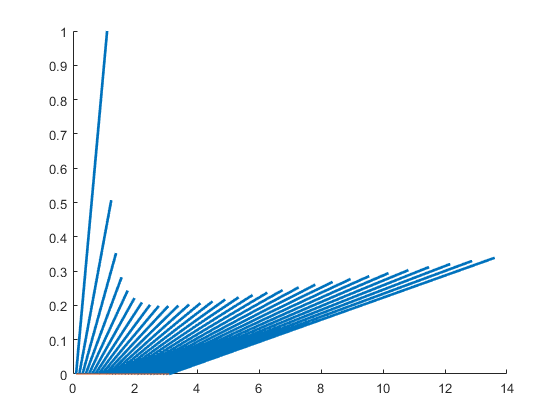

Y =     1.0000    1.0311    1.0834    1.1568    1.2515    1.3673    1.5044    1.6626    1.8420    2.0426    2.2644    2.5074    2.7716    3.0570    3.3635    3.6913    4.0402    4.4104    4.8017    5.2142    5.6479    6.1028    6.5789    7.0762    7.5947    8.1344    8.6952    9.2773    9.8805   10.5050
    1.0000    0.5069    0.3526    0.2820    0.2435    0.2215    0.2087    0.2017    0.1986    0.1981    0.1996    0.2025    0.2066    0.2116    0.2172    0.2235    0.2302    0.2373    0.2447    0.2524    0.2604    0.2685    0.2769    0.2854    0.2940    0.3028    0.3117    0.3206    0.3297    0.3388


hh.drawmesh(uinterval,vinterval,0);
hold on;
syms t;
u(t)=[0.1+t;0];
 hh.scale=0;
Y=hh.parallel_transport(u,[0;3],[1,1],30)

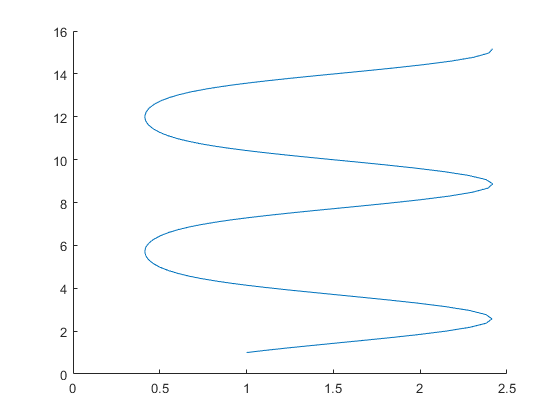

% length=reshape(Y,2,1,[]).*reshape(Y,1,2,[]).*hh.g
figure;
hh.drawmesh(uinterval,vinterval,0);
hold on;
hh.geodesic([0,100],[0.1, 0.1, 1, 1],100);